clear all
clc

data=readtable("realgdpgrowth.xlsx");

ar4 = arima(4, 0, 0);

Q1

pdi = data.pdi;  
mdl_1 = estimate(ar4, pdi); %model used and the y i want to estimate

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant      6.1137         1.278         4.7839      1.7189e-06
    AR{1}        0.14269      0.051047         2.7952       0.0051869
    AR{2}        0.13073      0.046139         2.8335       0.0046048
    AR{3}       -0.05952      0.042063         -1.415         0.15706
    AR{4}       -0.28709      0.041796        -6.8689      6.4705e-12
    Variance       385.2        21.032         18.315      6.2543e-75



%summarize(mdl_1)

[yForecast, yMSE] = forecast(mdl_1, 1, 'Y0', pdi);
%use mdl_1, do 1-step-ahead forecast, set pdi as y
%we get MSE since rootMSE ≈ stdf 

% Compute 90% confidence interval
ci_upper = yForecast + 1.645 * sqrt(yMSE);
ci_lower = yForecast - 1.645 * sqrt(yMSE);

% Display results
fprintf('Point Forecast for 2024Q4: %.4f\n', yForecast);

Point Forecast for 2024Q4: 6.8977


fprintf('90%% FI: [%.4f, %.4f]\n', ci_lower, ci_upper);

90% FI: [-25.3881, 39.1835]


The first lag appear to be most important since its coefficient is statistically significant and its magnitude is the biggest one among all coeffcients. The point forecast for 2024Q4 is 6.8977 and the 90% forecast interval is `[-25.3881, 39.1835].`

Q2

exports=data.exports;
mdl_2 = estimate(ar4, exports);

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant       5.5794        1.2333          4.5238      6.0725e-06
    AR{1}       -0.094329      0.046448         -2.0309         0.04227
    AR{2}         0.12891      0.052684          2.4468        0.014413
    AR{3}        0.059564      0.054531          1.0923          0.2747
    AR{4}       -0.052503      0.061814        -0.84937         0.39568
    Variance       299.59        12.974          23.093     5.4815e-118



%summarize(mdl_2);

% Forecast for 2024Q4 (one step ahead)
[yForecast_exp, yMSE_exp] = forecast(mdl_2, 1, 'Y0', exports);

% Compute 90% confidence interval
ci_upper_exp = yForecast_exp + 1.645 * sqrt(yMSE_exp);
ci_lower_exp = yForecast_exp - 1.645 * sqrt(yMSE_exp);

% Display results
fprintf('Exports Growth - Point Forecast for 2024Q4: %.4f\n', yForecast_exp);

Exports Growth - Point Forecast for 2024Q4: 4.5904


fprintf('90%% Confidence Interval: [%.4f, %.4f]\n', ci_lower_exp, ci_upper_exp);

90% Confidence Interval: [-23.8825, 33.0634]


The second lag appear to be most important since its coefficient is statistically significant and its magnitude is the biggest one among all coeffcients. The point forecast for 2024Q4 is 4.5904 and the 90% forecast interval is `[-23.8825, 33.0634]. `

Q3

% Extract the relevant series (assuming the column name is 'pdi_residential')
pdi_residential = data.pdi_residential;

% Remove missing values (if any)
pdi_residential = rmmissing(pdi_residential);

% Define AR(4) model
model_pdi_res = arima(4, 0, 0);

% Fit the model
estModel_pdi_res = estimate(model_pdi_res, pdi_residential);

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant       2.5922        1.1057          2.3444       0.019058
    AR{1}         0.47255      0.034384          13.743     5.5842e-43
    AR{2}        0.079359      0.047017          1.6879       0.091437
    AR{3}       0.0025396      0.051074        0.049724        0.96034
    AR{4}         -0.2311       0.05029         -4.5952     4.3229e-06
    Variance       293.43        16.162          18.156     1.1535e-73




% Forecast for 2024Q4 to 2025Q3 (4 quarters ahead)
nSteps = 4;
[yForecast_res, yMSE_res] = forecast(estModel_pdi_res, nSteps, 'Y0', pdi_residential);

% Compute 90% confidence intervals
upper = yForecast_res + 1.645 * sqrt(yMSE_res);
lower = yForecast_res - 1.645 * sqrt(yMSE_res);

% Create a time axis for plotting
future_quarters = linspace(2024.75, 2025.5, nSteps); % 2024Q4 to 2025Q3

fprintf('Point Forecast: %.4f\n', yForecast_res);

Point Forecast: -0.2049
Point Forecast: -1.0189
Point Forecast: 2.7306
Point Forecast: 4.7949


fprintf('90%% Confidence Interval: [%.4f, %.4f]\n', lower, upper);

90% Confidence Interval: [-28.3834, -32.1852]
90% Confidence Interval: [-29.5815, -27.9264]
90% Confidence Interval: [27.9736, 30.1473]
90% Confidence Interval: [35.0428, 37.5162]


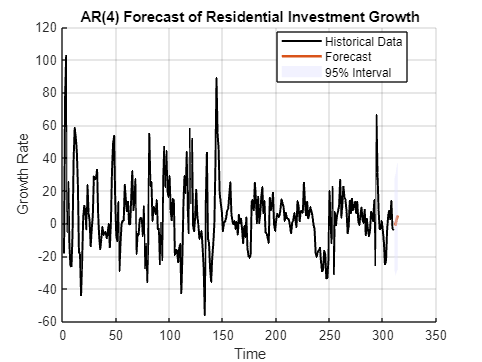


% Plot the forecasts with confidence intervals
% figure;
% plot(future_quarters, yForecast_res, '-o', 'LineWidth', 2, 'DisplayName', 'Forecast');
% hold on;
% plot(future_quarters, ci_upper_res, '--r', 'DisplayName', '90% CI Upper');
% plot(future_quarters, ci_lower_res, '--r', 'DisplayName', '90% CI Lower');
% xlabel('Year and Quarter');
% ylabel('Residential Investment Growth');
% title('Forecasts for PDI Residential Growth (AR(4) Model)');
% legend;
% grid on;
% hold off;
figure;
hold on;
t = (1:length(pdi_residential))';
plot(t, pdi_residential, 'k', 'LineWidth', 1.5);
future_t = length(pdi_residential)+(1:4);
plot(future_t, yForecast_res, 'LineWidth', 2);
fill([future_t fliplr(future_t)], [lower' fliplr(upper')], ...
     [0.9 0.9 1], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
title('AR(4) Forecast of Residential Investment Growth');
xlabel('Time');
ylabel('Growth Rate');
legend('Historical Data', 'Forecast', '95% Interval', 'Location', 'Best');
grid on;
hold off;

Q4(a)

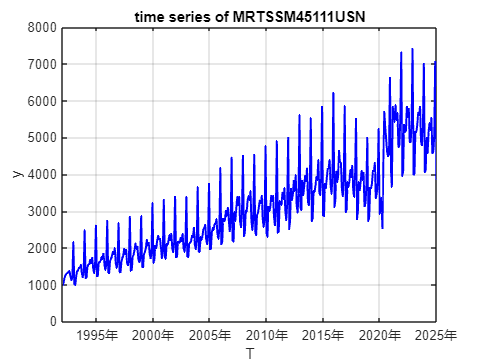

data4 = readtable('MRTSSM45111USN.xlsx', 'Sheet', 'Monthly');
y = data4.MRTSSM45111USN;
dates = datetime(data4.observation_date, 'InputFormat', 'yyyy-MM-dd');
T = length(y);
p = 12;    % lags
H = 12;    % horizon

%plot a 
figure;
plot(dates, y, 'b', 'LineWidth', 1.5);
hold on;
xlabel('T'); ylabel('y');
title('time series of MRTSSM45111USN');
grid on;

(b) I would use model with all trends, seasonal, cycles.

(c)

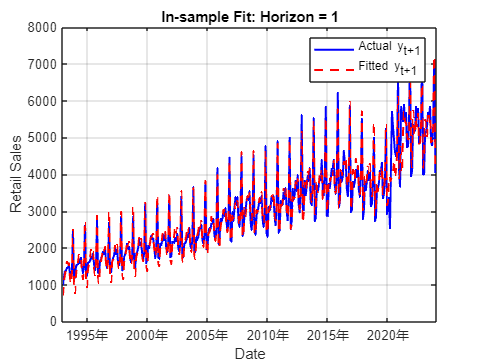


% STEP 2: Create trend and monthly dummies (length T)
trend_full = (1:T)';
month_num = month(dates);
month_dummy_full = dummyvar(categorical(month_num));
month_dummy_full(:,1) = [];  % remove first dummy to avoid multicollinearity

% STEP 3: Build lagged variables and target variables
n_obs = T - p - H;  % number of usable observations
X_lag = zeros(n_obs, p);
Y_all = zeros(n_obs, H);
trend = zeros(n_obs, 1);
seasonal_dummies = zeros(n_obs, 11);

for t = (p+1):(T-H)
    idx = t - p;
    X_lag(idx, :) = y(t-1:-1:t-p)';
    trend(idx) = trend_full(t);
    seasonal_dummies(idx, :) = month_dummy_full(t, :);
    for h = 1:H
        Y_all(idx, h) = y(t + h);
    end
end

% STEP 4: Combine all predictors 
X_all = [ones(n_obs, 1), trend, seasonal_dummies, X_lag];

% STEP 5: Forecasting model and confidence intervals
forecast_point = zeros(H, 1);
forecast_lower = zeros(H, 1);
forecast_upper = zeros(H, 1);
alpha = 0.10; % 90% CI
z = 1.645;



% direct method forecast each horizon from 1 to 12 by AR
x_last = [1, trend_full(end), month_dummy_full(end,:), y(end:-1:end-p+1)'];

for h = 1:H
    Y_h = Y_all(:, h);
    beta = (X_all' * X_all) \ (X_all' * Y_h);
    residuals = Y_h - X_all * beta;
    sigma = std(residuals);

    forecast_point(h) = x_last * beta;
    forecast_lower(h) = forecast_point(h) - z * sigma;
    forecast_upper(h) = forecast_point(h) + z * sigma;
end

% STEP 6: Create forecast date range 
forecast_dates = dates(end) + calmonths(1:H);
forecast_dates = forecast_dates(:);
all_dates = [dates; forecast_dates];

% STEP 7: Combine forecast and original data for plotting 
y_plot = [y; forecast_point];
lower_plot = [nan(T,1); forecast_lower];
upper_plot = [nan(T,1); forecast_upper];

% STEP 8: Only keep data from 2003 onward for clearer view
start_date = datetime(2003, 1, 1);
start_idx = find(all_dates >= start_date, 1, 'first');
T_total = length(y);

hist_y = y_plot(start_idx : T_total);
hist_dates = all_dates(start_idx : T_total);

pred_y = y_plot(T_total+1 : end);
pred_dates = all_dates(T_total+1 : end);
lower_pred = lower_plot(T_total+1 : end);
upper_pred = upper_plot(T_total+1 : end);

% STEP 9: Plot fitted values vs actual values (horizon = 1)
Y_true = Y_all(:, 1);
beta_1 = (X_all' * X_all) \ (X_all' * Y_true);
% beta = (X_all' * X_all) \ (X_all' * Y_h);
Y_fitted = X_all * beta_1;

fitted_start = dates(p+1);
fitted_end = dates(T - H);
fitted_dates = fitted_start : calmonths(1) : fitted_end;

%in sample fit plot
figure;
plot(fitted_dates, Y_true, 'b-', 'LineWidth', 1.5); hold on;
plot(fitted_dates, Y_fitted, 'r--', 'LineWidth', 1.5);
legend('Actual y_{t+1}', 'Fitted y_{t+1}');
xlabel('Date'); ylabel('Retail Sales');
title('In-sample Fit: Horizon = 1');
grid on;

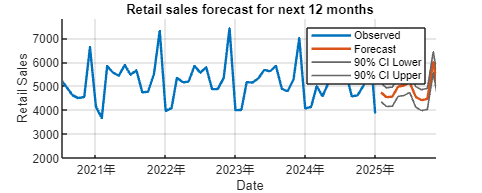



% STEP 10: Plot forecast with 90% confidence intervals
figure('Position', [100, 100, 1000, 400]);
hold on;
plot(hist_dates, hist_y,  'LineWidth', 1.8);               % historical
plot(pred_dates, pred_y,  'LineWidth', 1.8);               % point forecast
plot(pred_dates, lower_pred, 'Color', [0.4 0.4 0.4], 'LineWidth', 1.2); % lower CI
plot(pred_dates, upper_pred, 'Color', [0.4 0.4 0.4], 'LineWidth', 1.2); % upper CI
xlabel('Date'); ylabel('Retail Sales');
title('Retail sales forecast for next 12 months');
legend('Observed', 'Forecast', '90% CI Lower', '90% CI Upper');
grid on;
xlim([datetime(2020,7,12,16,3,42), datetime(2025,11,16,0,32,3)]);
ylim([1998 7802]);